## **Soft beam free fall** 

We created a 0.5m soft beam with radius linearly varying from 2cm to 1cm.

Torsion (x-axis) and bending (y- and z-axis) modes of deformation are enabled with a cubic strain.

SorosimLink (`L1`) and SorosimLinkage (`T1`) saved in `FreeFall.mat`

load('FreeFall.mat')

To see the properties of `L1`

L1

L1 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
         npie: 2
           ld: {[0.5000]}
            L: [0.5000]
           CS: 'C'
            r: {@(X1)X1.*(-1.0./1.0e+2)+1.0./5.0e+1}
            h: {[]}
            w: {[]}
            a: {[]}
            b: {[]}
           cx: []
           gi: {[4×4 double]}
           gf: {[4×4 double]}
            E: [1000000]
          Poi: [0.5000]
            G: [3.3333e+05]
          Eta: [10000]
          Rho: [1000]
           Kj: []
           Dj: []
            M: []
          n_l: [25]
          n_r: [18]
        color: [0.7655 0.7952 0.1869]
        alpha: [1]
          CPF: [0]
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: [0.0856]

To see the properties of S`1`

S1

S1 =   SorosimLinkage with properties:

                      N: 1
                   ndof: 12
                   nsig: 8
                     nj: 7
                 VLinks: [1×1 SorosimLink]
              LinkIndex: 1
                 CVRods: {[1×2 SorosimRod]}
                  iLpre: 0
                  g_ini: [4×4 double]
                Z_order: 4
               OneBasis: 0
                   nCLj: 0
                   iCLA: []
                   iCLB: []
               VRodsCLj: []
                  gACLj: []
                  gBCLj: []
           CLprecompute: [1×1 struct]
                   T_BS: []
                Gravity: 1
                      G: [6×1 double]
                     np: 0
            LocalWrench: [1×0 double]
                 Fp_loc: {0×1 cell}
                 Fp_vec: {0×1 cell}
                 Fp_sig: [0×1 double]
                    CEF: 0
             UnderWater: 0
              Rho

To see the problem definition:

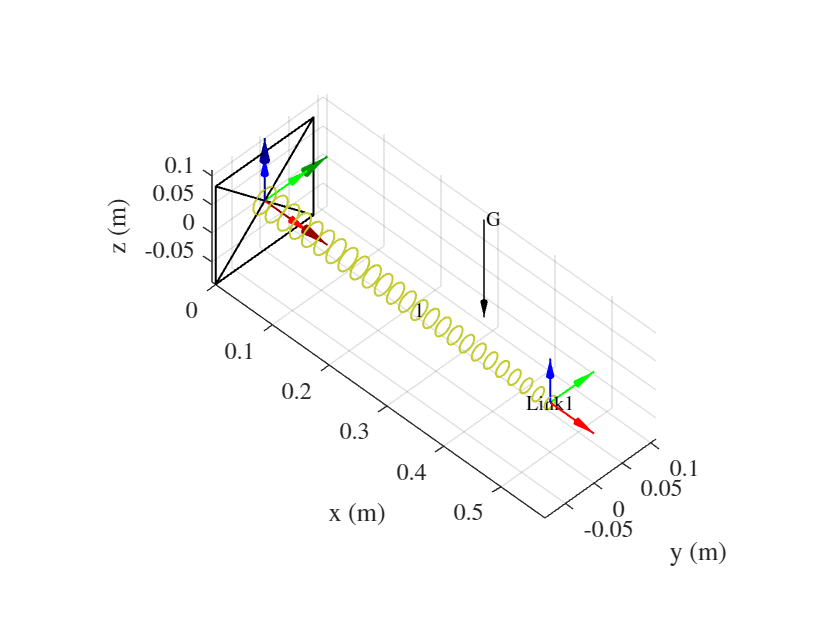

S1.plotq0

The result should be:

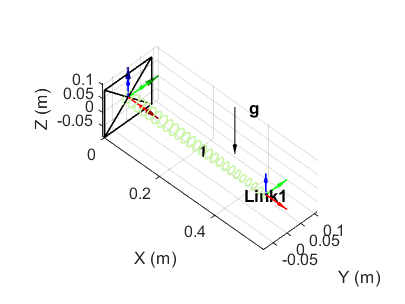

The beam is rigidly fixed at one end and subjected to gravity.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1         5.54674e+10                        2.44e+10              1
     1          2         7.87458e+09              1         1.38e+10              1
     2          3         3.41804e+07       0.845249         1.05e+09            2.5
     3          4             333.087      0.0363943         3.26e+06            2.5
     4          5          3.5536e-08    0.000111804             33.7            2.5
     5          6         8.40864e-21     1.1991e-09         5.17e-06            2.5
     6          7         8.40864e-21    1.26046e-14         5.17e-06            2.5

Equation solved, solver stalled.

fsolve stopped because the relative 

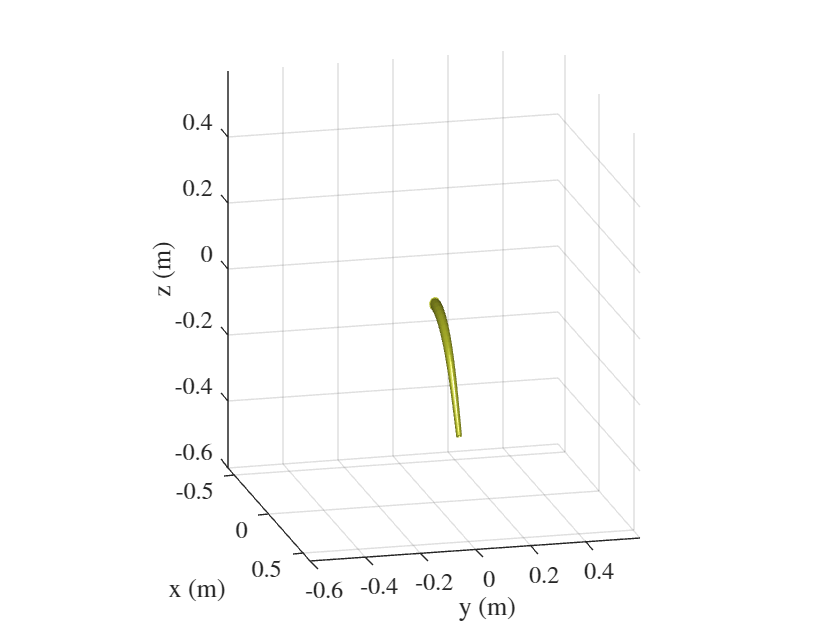

q=S1.statics;

A dialog box will pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

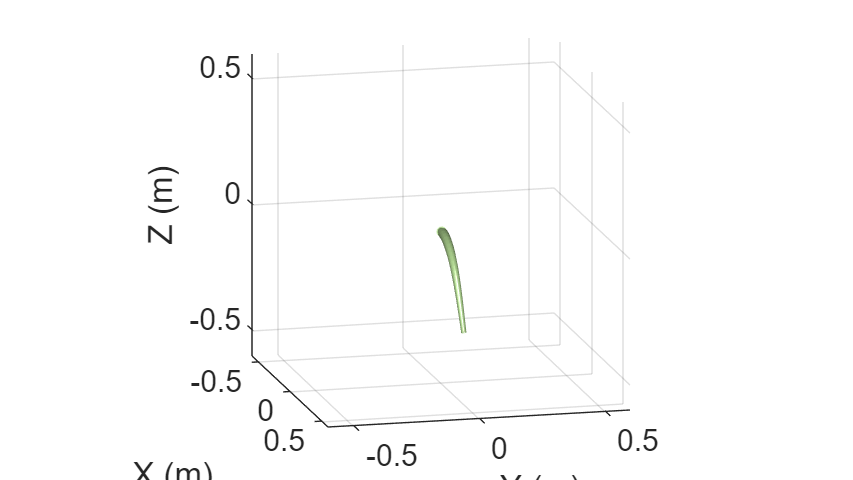

### **Damped dynamics**

For dynamics problem, type:

    1.8356
Elapsed time is 0.382333 seconds.


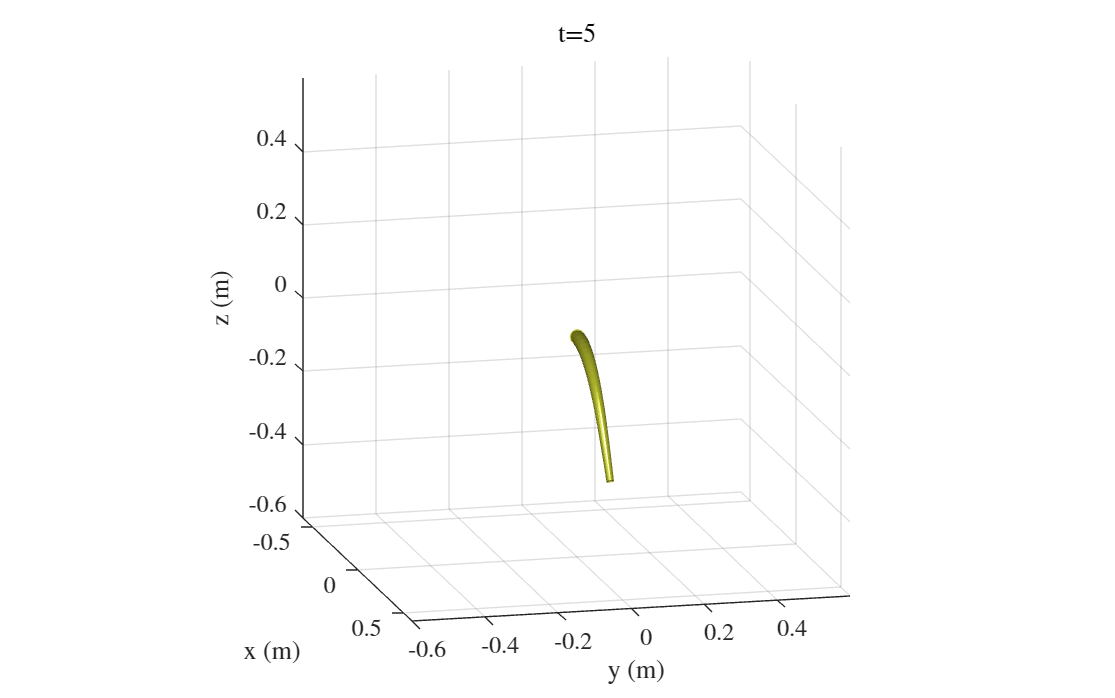

[t,qqd]=S1.dynamics;

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.mp3` will be saved in the folder.

Energy computations can be made by running energy.m after the dynamic simulation is complete

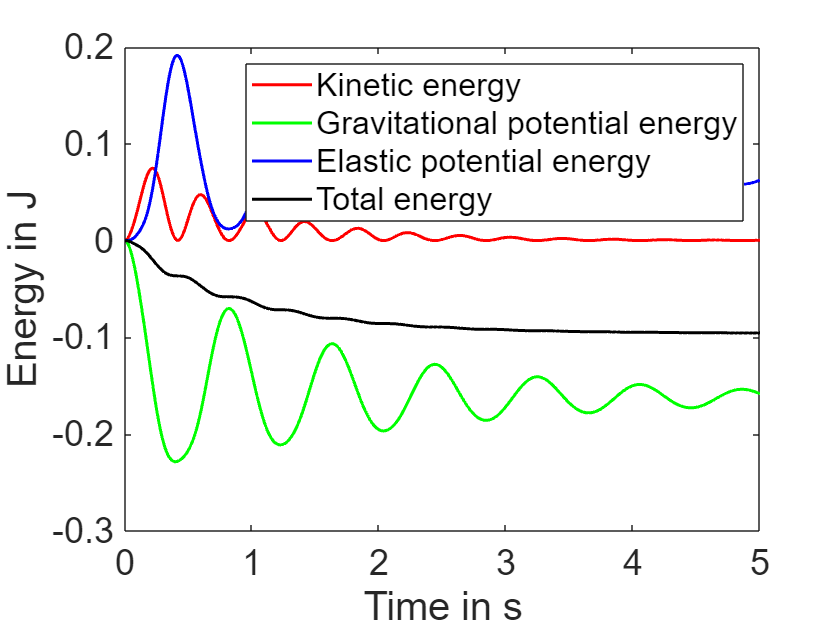

energy

### **Undamped dynamics**

To turn off the elastic damping of the system type:

S1.Damped=false;

We run the dynamic simulation again. This time total energy must stay constant!

    0.6187
    1.3330
    2.1844
    3.2326
    4.2621
Elapsed time is 0.961686 seconds.


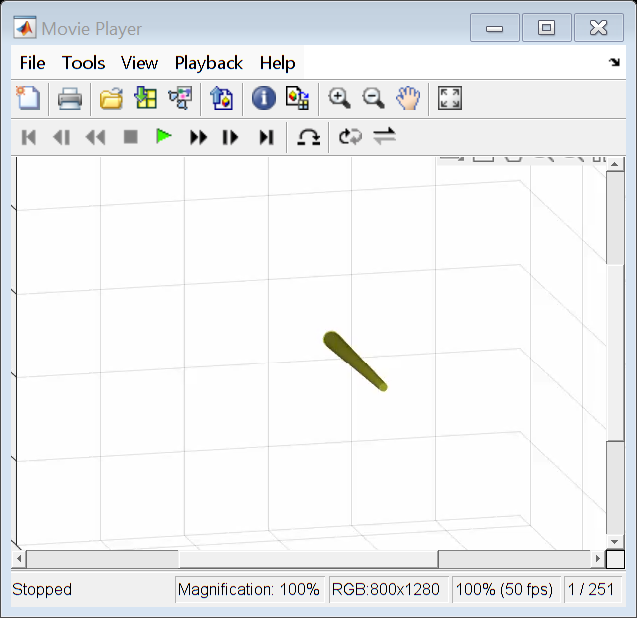

[t,qqd]=S1.dynamics;

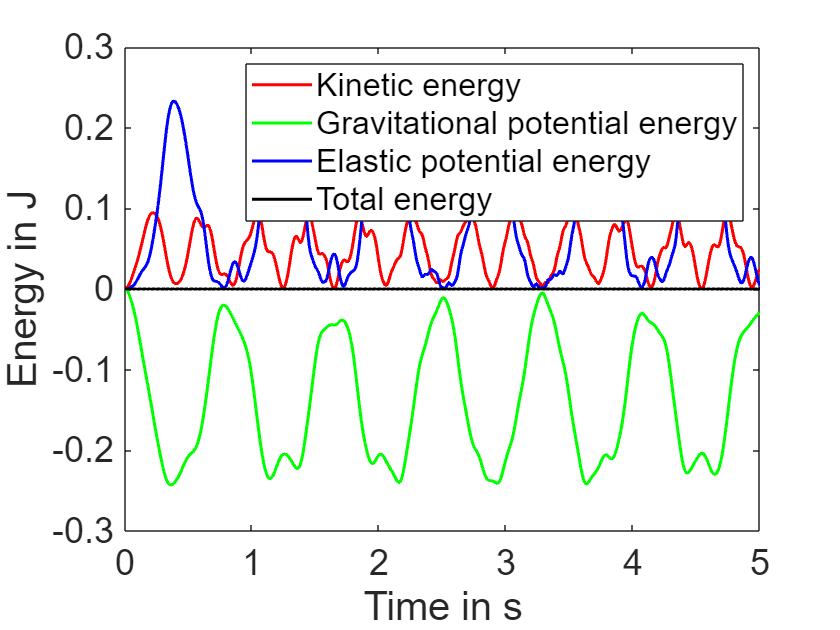

energy